# Cartoon of msd showing superdiffusive vs diffusive vs subdiffusive movement

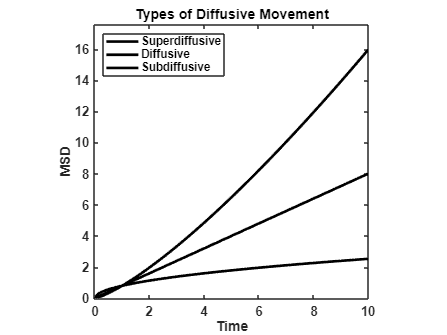

% Create a new figure window and clear it
figure;
clf;

% --- Define Variables ---
% Create a time vector from 0 to 10
time = linspace(0, 10, 100);

% Define the mathematical relationships for diffusion types
% MSD is proportional to time^alpha, where alpha determines the type of diffusion.
D = 0.8; % A sample diffusion coefficient to scale the lines

% 1. Normal Diffusion (alpha = 1): A straight line
msd_diffusive = D * time.^1.0;

% 2. Superdiffusion (alpha > 1): A curve opening upwards
msd_superdiffusive = D * time.^1.3;

% 3. Subdiffusion (alpha < 1): A curve opening downwards
msd_subdiffusive = D * time.^0.5;


% --- Plot the Data ---
% Use 'hold on' to plot all lines on the same axes
hold on;

% Plot the three lines with specified colors and increased line width for clarity
plot(time, msd_superdiffusive, 'k', 'LineWidth', 2.5);
plot(time, msd_diffusive, 'k', 'LineWidth', 2.5);
plot(time, msd_subdiffusive, 'k', 'LineWidth', 2.5);

% Release the hold on the plot
hold off;


% --- Add Labels and Formatting ---
% Add labels to the x and y axes
xlabel('Time');
ylabel('MSD');

% Add a title to the plot
title('Types of Diffusive Movement');

% Add a legend to identify each line. 'Location' places it in the best spot.
legend('Superdiffusive', 'Diffusive', 'Subdiffusive', 'Location', 'northwest');

% Set axis limits for a clean look
xlim([0, max(time)]);
ylim([0, max(msd_superdiffusive)*1.1]); % Add 10% padding to the top

% Add a grid and a box around the plot for better readability

box on;
axis square
grid off


% Optional: Improve the general appearance
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

# Emergent behavior with different bead sizes

% Mechanism-Based Transport Simulation (Unified Physics + Visualization)
close all; clear; clc;

%% 1. Parameters
dt = 0.05;                  % seconds
simulation_time = 60;       % seconds
n_steps = simulation_time / dt;
n_simulations = 100;         % More particles for smooth averages

% Bead Sizes
bead_configs = [5, 100];    

% Conditions
conditions = struct('name', {'Empty', 'Active'}, ...
                    'has_cilia', {false, true}, ...
                    'color', {'b', 'g'});

% Physics Constants (In MICRON Units)
kB = 1.38e-23;              
T = 298;                    
eta = 1e-3;                 % Pa.s
% Drag coefficient factor (6*pi*eta) converted for micron output
drag_factor = 6 * pi * eta * 1e-6; 

% Mechanism Parameters
% 1. Obstacle Parameters (For 5um)
cilia_spacing = 6;          % Average gap between obstacles (um)
cilia_stem_rad = 0.8;       % Radius of the obstacle (um)

% 2. Active Parameters (For 100um)
% The 'kick' velocity provided by cilia beating
kick_velocity = 2.0;        % um/s (Magnitude of active noise)

%% 2. Generate Landscape
% We generate a fixed field of obstacles
L = 500; % Domain size
num_cilia = round((L/cilia_spacing)^2);
obs_x = (rand(num_cilia,1)-0.5)*L;
obs_y = (rand(num_cilia,1)-0.5)*L;
tree = KDTreeSearcher([obs_x, obs_y]);

%% 3. Main Loop
results = struct();

for b_idx = 1:length(bead_configs)
    diam = bead_configs(b_idx);
    rad = diam / 2;
    
    % Calculate Diffusion Coefficient (Micron^2/s)
    gamma = drag_factor * rad; % Drag in SI
    D_si = (kB * T) / gamma;   % m^2/s
    D = D_si * 1e12;           % um^2/s
    
    fprintf('Bead: %d um, D: %.4f um^2/s\n', diam, D);
    
    % REGIME CHECK:
    is_immersed = diam < cilia_spacing * 2; 

    for c_idx = 1:length(conditions)
        cond = conditions(c_idx);
        msd_sum = zeros(1, n_steps);
        
        for sim = 1:n_simulations
            x = 0; y = 0;
            traj_x = zeros(1, n_steps);
            traj_y = zeros(1, n_steps);
            
            for t = 1:n_steps
                
                % 1. Base Brownian Motion (Always present)
                dx = sqrt(2*D*dt) * randn();
                dy = sqrt(2*D*dt) * randn();
                
                % 2. Cilia Interactions
                if cond.has_cilia
                    if is_immersed
                        % --- REGIME: HINDERED DIFFUSION ---
                        % Proposed new position
                        x_new = x + dx;
                        y_new = y + dy;
                        
                        % Check for collisions with stems
                        search_r = rad + cilia_stem_rad;
                        idx = rangesearch(tree, [x_new, y_new], search_r);
                        
                        if ~isempty(idx{1})
                            % COLLISION DETECTED: Bounce/Reject
                            dx = dx * -0.5; 
                            dy = dy * -0.5;
                        end
                        
                    else
                        % --- REGIME: ACTIVE BATH ---
                        % Bead sits on top, receives random kicks
                        angle = rand() * 2 * pi;
                        dx_kick = cos(angle) * kick_velocity * dt;
                        dy_kick = sin(angle) * kick_velocity * dt;
                        
                        dx = dx + dx_kick;
                        dy = dy + dy_kick;
                    end
                end
                
                x = x + dx;
                y = y + dy;
                
                traj_x(t) = x;
                traj_y(t) = y;
            end
            msd_sum = msd_sum + (traj_x.^2 + traj_y.^2);
        end
        results(b_idx, c_idx).time = (1:n_steps)*dt;
        results(b_idx, c_idx).msd = msd_sum / n_simulations;
    end
end

Bead: 5 um, D: 0.0873 um^2/s
Bead: 100 um, D: 0.0044 um^2/s


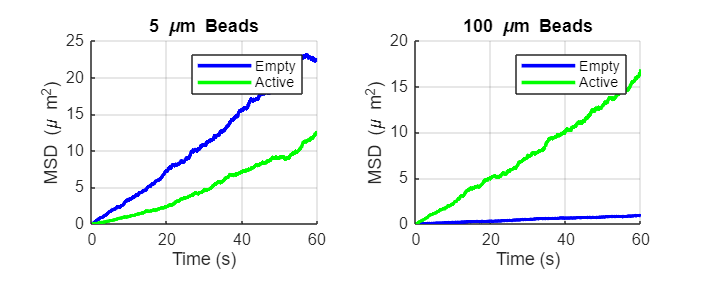


%% 4. Plotting MSD Results
figure('Position', [100, 400, 1000, 400], 'Color', 'w');
tiledlayout(1,2);

% 5 micron Plot
nexttile; hold on; title('5 \mum Beads');
plot(results(1,1).time, results(1,1).msd, 'b', 'LineWidth', 2); % Empty
plot(results(1,2).time, results(1,2).msd, 'g', 'LineWidth', 2); % Active
xlabel('Time (s)'); ylabel('MSD (\mu m^2)'); grid off; legend('Empty', 'Active');

% 100 micron Plot
nexttile; hold on; title('100 \mum Beads');
plot(results(2,1).time, results(2,1).msd, 'b', 'LineWidth', 2); % Empty
plot(results(2,2).time, results(2,2).msd, 'g', 'LineWidth', 2); % Active
xlabel('Time (s)'); ylabel('MSD (\mu m^2)'); grid off; legend('Empty', 'Active');

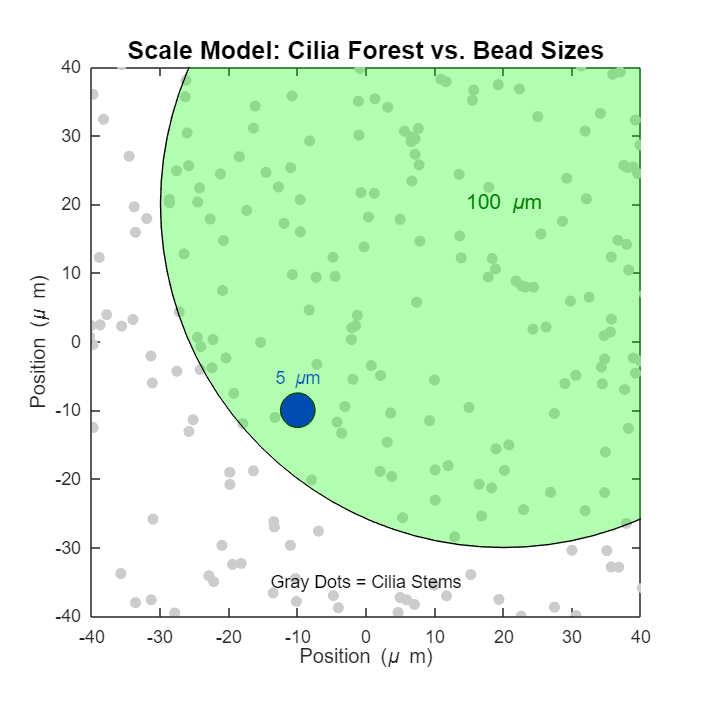



%% 5. VISUALIZATION OF SCALE (The requested Figure)
figure('Position', [100, 50, 600, 600], 'Color', 'w');
axis equal; hold on; box on;
title('Scale Model: Cilia Forest vs. Bead Sizes', 'FontSize', 14);
xlabel('Position (\mu m)'); ylabel('Position (\mu m)');

% A. Draw the Cilia Patch (Zoomed in area)
vis_range = 80; % View window size
xlim([-vis_range/2, vis_range/2]);
ylim([-vis_range/2, vis_range/2]);

% Filter cilia to only draw those in view
in_view = abs(obs_x) < vis_range/2 + 5 & abs(obs_y) < vis_range/2 + 5;
cx = obs_x(in_view);
cy = obs_y(in_view);

% Draw Cilia Stems (Gray circles)
for i = 1:length(cx)
    rectangle('Position', [cx(i)-cilia_stem_rad, cy(i)-cilia_stem_rad, ...
              cilia_stem_rad*2, cilia_stem_rad*2], ...
              'Curvature', [1 1], 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');
end

% B. Draw 5um Bead (Blue)
% Place it in a gap near the center
r5 = 2.5;
rectangle('Position', [-10-r5, -10-r5, r5*2, r5*2], ...
          'Curvature', [1 1], 'FaceColor', 'b', 'EdgeColor', 'k');
text(-10, -10+r5+2, '5 \mum', 'Color', 'b', 'HorizontalAlignment', 'center');

% C. Draw 100um Bead (Green, transparent)
% Place it offset so it dominates the view
r100 = 50;
rectangle('Position', [20-r100, 20-r100, r100*2, r100*2], ...
          'Curvature', [1 1], 'FaceColor', 'g', 'EdgeColor', 'k', ...
          'FaceAlpha', 0.3); % FaceAlpha requires MATLAB R2014b or later
text(20, 20, '100 \mum', 'Color', [0 0.5 0], 'HorizontalAlignment', 'center', 'FontSize', 12);

% Add Annotation
text(0, -vis_range/2 + 5, 'Gray Dots = Cilia Stems', 'HorizontalAlignment', 'center');

# Changing Cilia density


% Cilia Spacing Parameter Sweep Simulation
% Plots Effective Diffusion vs. Cilia Spacing
close all; clear; clc;

%% 1. Setup Parameters
spacings = [ 3, 4, 5, 6, 7,  8, 9, 10, 11, 12, 15, 20]; % Microns
bead_sizes = [5, 100];               % Microns

% Simulation Settings
dt = 0.05;
n_steps = 1000; % Short bursts for D estimation
n_particles = 500; % Higher N for smooth averages

% Physical Constants
kB = 1.38e-23; T = 298; eta = 1e-3;
drag_conversion = 6 * pi * eta * 1e-6; % Drag factor in SI

% Active Settings
base_kick_vel = 2.0;       % Reference kick velocity at standard density
ref_spacing = 6.0;         % Reference spacing for density scaling

%% 2. Data Storage
% Structure: data(bead_idx).active_D(spacing_idx)
data = struct(); 

%% 3. The Sweep Loop
fprintf('Starting Parameter Sweep...\n');

Starting Parameter Sweep...



for b_idx = 1:length(bead_sizes)
    b_diam = bead_sizes(b_idx);
    b_rad = b_diam / 2;
    
    % Theoretical Passive D (Stokes-Einstein)
    gamma = drag_conversion * b_rad;
    D_passive_val = (kB * T / gamma) * 1e12; % um^2/s
    
    % Store Passive Line (Constant)
    data(b_idx).passive_D = ones(size(spacings)) * D_passive_val;
    data(b_idx).active_D = zeros(size(spacings));
    
    fprintf('  Simulating Bead Size: %d um\n', b_diam);
    
    for s_idx = 1:length(spacings)
        space_val = spacings(s_idx);
        
        % --- GENERATE GEOMETRY FOR THIS SPACING ---
        L = 300; % Domain size
        num_obs = round((L/space_val)^2);
        obs_x = (rand(num_obs,1)-0.5)*L;
        obs_y = (rand(num_obs,1)-0.5)*L;
        tree = KDTreeSearcher([obs_x, obs_y]);
        
        % --- DETERMINE REGIME ---
        % Filter Logic: If gap > bead, bead goes in. If gap < bead, bead sits on top.
        % We estimate gap approx spacing - stem_diameter
        stem_diam = 1.0; 
        gap = space_val - stem_diam;
        
        is_immersed = b_diam < gap; 
        
        % --- RUN PARTICLES ---
        msd_end_sum = 0;
        
        parfor p = 1:n_particles
            x = 0; y = 0;
            
            % Scale Active Kick by Density (Denser = Stronger/More Frequent Kicks)
            % Density scales as 1/spacing^2.
            % We scale velocity magnitude by sqrt(density) -> 1/spacing
            % to represent incoherent addition of random kicks.
            current_kick = base_kick_vel * (ref_spacing / space_val);
            
            for t = 1:n_steps
                % 1. Brownian
                dx = sqrt(2*D_passive_val*dt) * randn();
                dy = sqrt(2*D_passive_val*dt) * randn();
                
                % 2. Interaction
                if is_immersed
                    % HINDERED (Collision)
                    x_new = x + dx; y_new = y + dy;
                    search_r = b_rad + (stem_diam/2);
                    idx = rangesearch(tree, [x_new, y_new], search_r);
                    if ~isempty(idx{1})
                        dx = dx * -0.5; % Bounce/Slow
                        dy = dy * -0.5;
                    end
                else
                    % ACTIVE (Surface)
                    % Random Kick
                    ang = rand()*2*pi;
                    dx = dx + cos(ang)*current_kick*dt;
                    dy = dy + sin(ang)*current_kick*dt;
                end
                
                x = x + dx; y = y + dy;
            end
            msd_end_sum = msd_end_sum + (x^2 + y^2);
        end
        
        % Calculate D from MSD at end time
        % MSD = 4 * D * t
        mean_msd = msd_end_sum / n_particles;
        total_time = n_steps * dt;
        calc_D = mean_msd / (4 * total_time);
        
        data(b_idx).active_D(s_idx) = calc_D;
    end
end

  Simulating Bead Size: 5 um
  Simulating Bead Size: 100 um


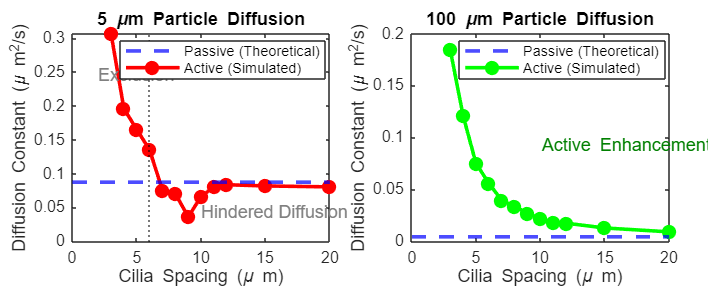


%% 4. Plotting
figure('Position', [100, 100, 1200, 500], 'Color', 'w');
tiledlayout(1,2, 'Padding', 'compact', 'TileSpacing', 'compact');

% --- FIGURE 1: 5 micron Bead ---
nexttile; hold on; grid off; box on;
b_idx = 1;
% Plot Passive (Baseline)
yline(data(b_idx).passive_D(1), 'b--', 'LineWidth', 2, 'DisplayName', 'Passive (Theoretical)');
% Plot Active (Simulated)
plot(spacings, data(b_idx).active_D, 'ro-', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'DisplayName', 'Active (Simulated)');

title('5 \mum Particle Diffusion');
xlabel('Cilia Spacing (\mu m)');
ylabel('Diffusion Constant (\mu m^2/s)');
legend('Location', 'best');
% Add annotations for regime
x_trans = 5 + 1; % approx where bead fits
xline(x_trans, 'k:', 'HandleVisibility', 'off');
text(2, max(data(b_idx).active_D)*0.8, 'Exclusion', 'Color', [0.5 0.5 0.5]);
text(10, min(data(b_idx).active_D)*1.2, 'Hindered Diffusion', 'Color', [0.5 0.5 0.5]);

% --- FIGURE 2: 100 micron Bead ---
nexttile; hold on; grid off; box on;
b_idx = 2;
% Plot Passive (Baseline)
yline(data(b_idx).passive_D(1), 'b--', 'LineWidth', 2, 'DisplayName', 'Passive (Theoretical)');
% Plot Active (Simulated)
plot(spacings, data(b_idx).active_D, 'go-', 'LineWidth', 2, 'MarkerFaceColor', 'g', 'DisplayName', 'Active (Simulated)');

title('100 \mum Particle Diffusion');
xlabel('Cilia Spacing (\mu m)');
ylabel('Diffusion Constant (\mu m^2/s)');
legend('Location', 'best');
text(10, max(data(b_idx).active_D)*0.5, 'Active Enhancement \propto Density', 'Color', [0 0.5 0]);